# process measurement

## options

clear
Fs=5000000

Fs = 5000000

windowSize=2^20 ;
window=hamming(windowSize);
overlap=windowSize/2;
nfft=2^19;
T=5;%sec (max 10)
N=Fs*T;
%t = (0:L-1)*T;        % Time vector
centerfreq=2403000000;

## load files

%y0=wavFile2complex('04-May-2023 113223.846 2403.000MHz.wav',N);%0 beacons

% y0=iqFile2complex('16_aug_sample1',N);% 0.5 m
% y1=iqFile2complex('16_aug_sample2',N);%1 m
% y2=iqFile2complex('16_aug_sample3',N);%1.5 m
% y3=iqFile2complex('16_aug_sample4',N);%2 m
% y4=iqFile2complex('04_aug_sample2',N);%laptop

y0=iqFile2complex('10_aug_sample0',N);% 0 beacons
y1=iqFile2complex('10_aug_sample1',N);%1 beacons
y2=iqFile2complex('10_aug_sample2',N);%2 beacons
%y3=iqFile2complex('10_aug_sample3',N);%3 beacons
y4=iqFile2complex('04_aug_sample2',N);%laptop

% y0=iqFile2complex('17_aug_sample2',N);% mouse
% y1=iqFile2complex('10_aug_sample1',N);%1 beacons
% y2=iqFile2complex('17_aug_sample1',N);%phone
 y3=iqFile2complex('15_aug_sample1',N);%phone + earbuds
% y4=iqFile2complex('04_aug_sample2',N);%laptop

% remove dc components
y0=y0-mean(y0);
y1=y1-mean(y1);
y2=y2-mean(y2);
y3=y3-mean(y3);
y4=y4-mean(y4);

## fft

% fftI=fft(real(y4));
% fftQ=fft(imag(y4));
% subplot(1,2,1); plot(abs(fftI)); title('abs fftI');
% subplot(1,2,2); plot(abs(fftQ)); title('abs fftQ');

## stft

[s0, f0, t0]=spectrogram(y0, window,overlap,nfft,Fs,'power','centered', 'yaxis');%signal,window,noverlap,nfft,Fs
% plotSpectrogram(s0,f0,t0,centerfreq);

[s1, f1, t1]=spectrogram(y1, window,overlap,nfft,Fs,'power','centered', 'yaxis');%signal,window,noverlap,nfft,Fs
% plotSpectrogram(s1,f1,t1,centerfreq);

[s2, f2, t2]=spectrogram(y2, window,overlap,nfft,Fs,'power','centered', 'yaxis');%signal,window,noverlap,nfft,Fs
% plotSpectrogram(s2,f2,t2,centerfreq);

[s3,f3, t3]=spectrogram(y3, window,overlap,nfft,Fs,'power','centered', 'yaxis');%signal,window,noverlap,nfft,Fs
% plotSpectrogram(s3,f3,t3,centerfreq);

[s4,f4, t4]=spectrogram(y4, window,overlap,nfft,Fs,'power','centered', 'yaxis');%signal,window,noverlap,nfft,Fs
% plotSpectrogram(s4,f4,t4,centerfreq);

## properties

% R=50;
% K=1;
% %V_peak=sqrt(real(y0).^2+imag(y0).^2);
% %V_rms=V_peak./sqrt(2);
% %P_rms=(V_rms.^2)./R;
% P_rms=(real(y0).^2+imag(y0).^2)/(2*R);
% meanP_rms = mean(P_rms)
% P_dBm=10*log10(P_rms./0.001);
% meanP_dBm=mean(P_dBm)
% pRMS=(1/R)*(real(y0).^2+imag(y0).^2)/2;
% meanPrms=mean(pRMS)
% meanPdBm=mean(10*log10((real(y0).^2+imag(y0).^2)/(R*0.001)))
% power_W = 1/N * sum(real(y0).^2 + (imag(y0).^2)) * K / R
% power_dBm=10*log10 (power_W/0.001)



%mask to hide DC component
% mask=ones(length(sumS0),1);
% mask(floor(length(sumS0)/2-0.025*length(sumS0)):floor(length(sumS0)/2+0.025*length(sumS0)))=0;

ref0_L=1.4648e+09;
ref0_H=1.4601e+09;
ref1_L = 5.4462e+10;
ref1_H = 2.2985e+10;


meanS0dB=mean(abs(10*log10(s0)),2);
meanS0=mean(abs(s0),2);
meanS0_Low=mean(meanS0(1:floor(length(meanS0)*0.5)))

meanS0_Low = 1.4648e+09

meanS0_High=mean(meanS0(floor(length(meanS0)*0.5:length(meanS0))))

meanS0_High = 1.4601e+09

ratio0=meanS0_Low/meanS0_High

ratio0 = 1.0032

LL0ratio0=meanS0_Low/ref0_L

LL0ratio0 = 1.0000

LL1ratio0=meanS0_Low/ref1_L

LL1ratio0 = 0.0269


meanS1dB=mean(abs(10*log10(s1)),2);
meanS1=mean(abs(s1),2);
meanS1_Low=mean(meanS1(1:floor(length(meanS1)*0.5)))

meanS1_Low = 5.4462e+10

meanS1_High=mean(meanS1(floor(length(meanS1)*0.5:length(meanS1))))

meanS1_High = 2.2985e+10

ratio1=meanS1_Low/meanS1_High

ratio1 = 2.3694

LL0ratio1=meanS1_Low/ref0_L

LL0ratio1 = 37.1803

LL1ratio1=meanS1_Low/ref1_L

LL1ratio1 = 1.0000


meanS2dB=mean(abs(10*log10(s2)),2);
meanS2=mean(abs(s2),2);
meanS2_Low=mean(meanS2(1:floor(length(meanS2)*0.5)))

meanS2_Low = 7.8240e+10

meanS2_High=mean(meanS2(floor(length(meanS2)*0.5:length(meanS2))))

meanS2_High = 3.1290e+10

ratio2=meanS2_Low/meanS2_High

ratio2 = 2.5005

LL0ratio2=meanS2_Low/ref0_L

LL0ratio2 = 53.4137

LL1ratio2=meanS2_Low/ref1_L

LL1ratio2 = 1.4366


meanS3dB=mean(abs(10*log10(s3)),2);
meanS3=mean(abs(s3),2);
meanS3_Low=mean(meanS3(1:floor(length(meanS3)*0.5)))

meanS3_Low = 1.3414e+11

meanS3_High=mean(meanS3(floor(length(meanS3)*0.5:length(meanS3))))

meanS3_High = 1.5343e+11

ratio3=meanS3_Low/meanS3_High

ratio3 = 0.8743

LL0ratio3=meanS3_Low/ref0_L

LL0ratio3 = 91.5768

LL1ratio3=meanS3_Low/ref1_L

LL1ratio3 = 2.4630



meanS4dB=mean(abs(10*log10(s4)),2);
meanS4=mean(abs(s4),2);
meanS4_Low=mean(meanS4(1:floor(length(meanS4)*0.5)))

meanS4_Low = 4.7705e+10

meanS4_High=mean(meanS4(floor(length(meanS4)*0.5:length(meanS4))))

meanS4_High = 2.0045e+10

ratio4=meanS4_Low/meanS4_High

ratio4 = 2.3799

LL0ratio4=meanS4_Low/ref0_L

LL0ratio4 = 32.5677

LL1ratio4=meanS4_Low/ref1_L

LL1ratio4 = 0.8759




% sumS1=mean(abs(10*log10(s1)),2);
% sumS1_masked=sumS1;%.*mask;
% totalS1_Low=mean(sumS1_masked(1:floor(length(sumS1)*0.5)))
% totalS1_High=mean(sumS1_masked(floor(length(sumS1)*0.5:length(sumS1))))
% ratio1=10^(totalS1_Low/10)/10^(totalS1_High/10)
% 
% sumS2=mean(abs(10*log10(s2)),2);
% sumS2_masked=sumS2;%.*mask;
% totalS2_Low=mean(sumS2_masked(1:floor(length(sumS2)*0.5)))
% totalS2_High=mean(sumS2_masked(floor(length(sumS2)*0.5:length(sumS2))))
% ratio2=10^(totalS2_Low/10)/10^(totalS2_High/10)
% 
% sumS3=mean(abs(10*log10(s3)),2);
% sumS3_masked=sumS3;%.*mask;
% totalS3_Low=mean(sumS3_masked(1:floor(length(sumS3)*0.5)))
% totalS3_High=mean(sumS3_masked(floor(length(sumS3)*0.5:length(sumS3))))
% ratio3=10^(totalS3_Low/10)/10^(totalS3_High/10)
% 
% sumS4=mean(abs(10*log10(s4)),2);
% sumS4_masked=sumS4;%.*mask;
% totalS4_Low=mean(sumS4_masked(1:floor(length(sumS4)*0.5)))
% totalS4_High=mean(sumS4_masked(floor(length(sumS4)*0.5:length(sumS4))))
% ratio4=10^(totalS4_Low/10)/10^(totalS4_High/10)


## plot

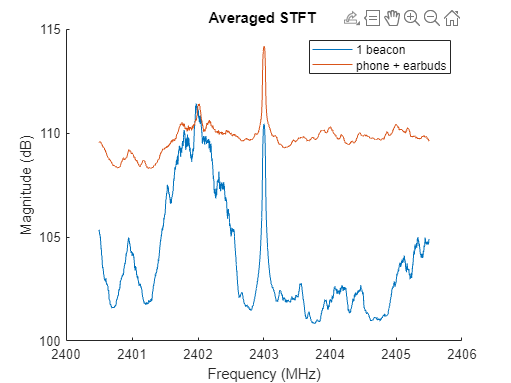

hold off
hold on
k=5000;

%plot((f0+centerfreq)./1e6,movmean(meanS0dB,k),'DisplayName','0.5 m');

plot((f1+centerfreq)./1e6,movmean(meanS1dB,k),'DisplayName','1 beacon');

%plot((f2+centerfreq)./1e6,movmean(meanS2dB,k),'DisplayName','1.5 m');

plot((f1+centerfreq)./1e6,movmean(meanS3dB,k),'DisplayName','phone + earbuds');
legend;

%plot((f4+centerfreq)./1e6,movmean(meanS4dB,k),'DisplayName','laptop');
title('Averaged STFT ');
ylabel('Magnitude (dB)');
xlabel('Frequency (MHz)');
legend;
hold off

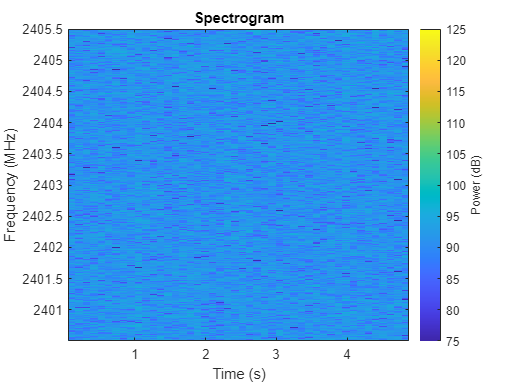

plotSpectrogram(s0,f0,t0,centerfreq);

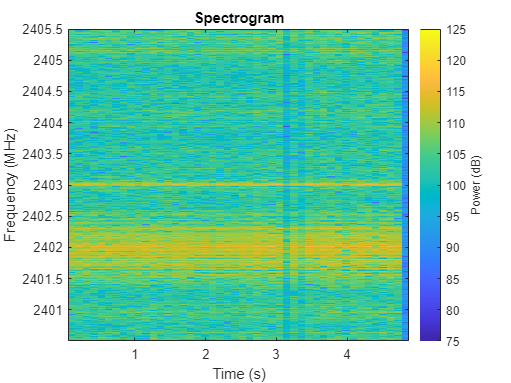

plotSpectrogram(s1,f1,t1,centerfreq);

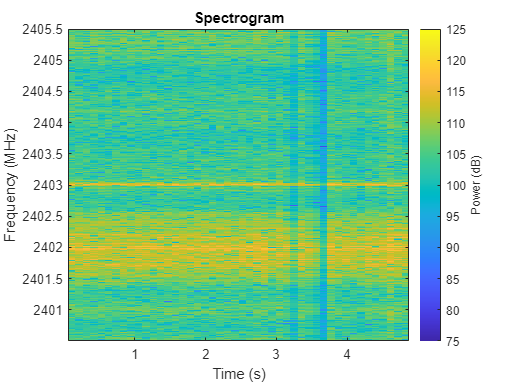

plotSpectrogram(s2,f2,t2,centerfreq);

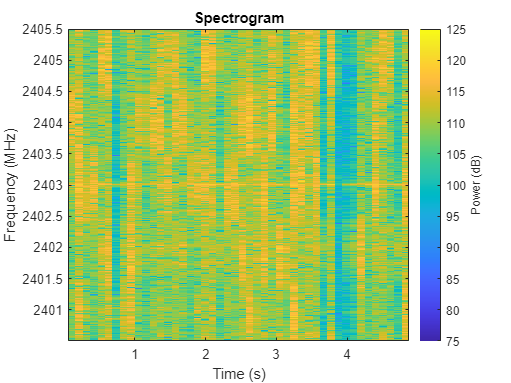

plotSpectrogram(s3,f3,t3,centerfreq);

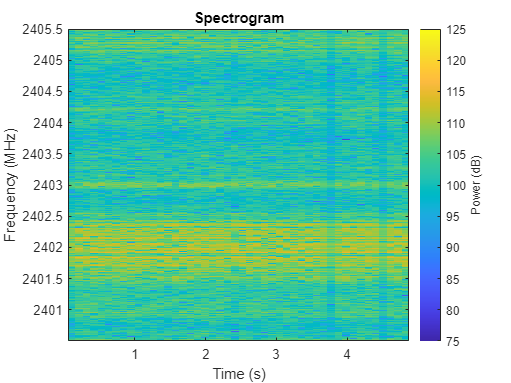

plotSpectrogram(s4,f4,t4,centerfreq);